% Generate random signal, 
AL_ref = [2,0,2,0,0,9,3,3,4]; % Andrew's student number
FC_ref = [2,0,2,0,3,2,1,1,7]; % Frank's student number
x1 = repmat(AL_ref,1,100) 
x1 = x1 - repmat(mean(x1),1,900)
x2 = repmat(FC_ref,1,100) 
x2 = x2 - repmat(mean(x2),1,900)
fs = round((9334+2117)/2)

fs = 5726

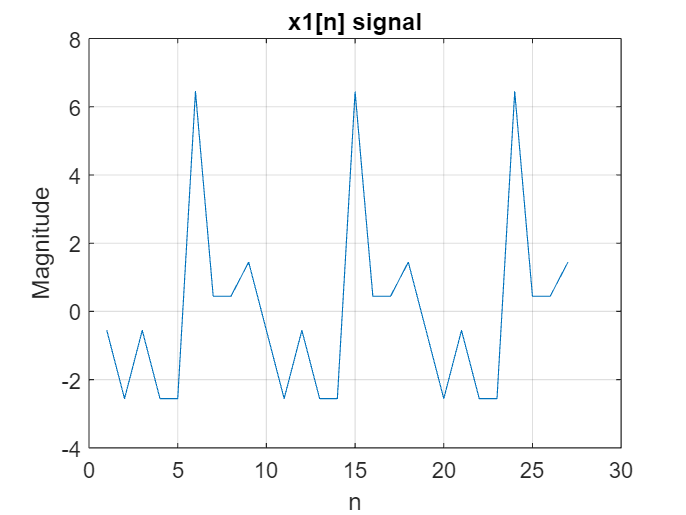



% Plot time signals
figure;
plot(1:27,x1(1:27));
title('x1[n] signal')
xlabel('n');
ylabel('Magnitude');
grid on;

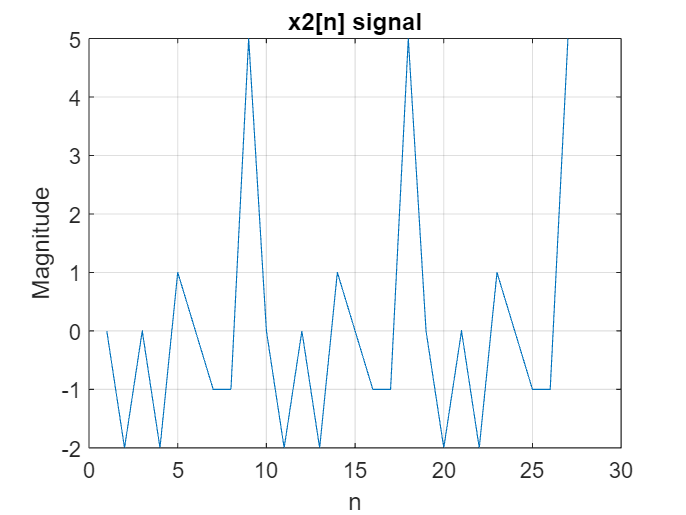

figure;
plot(1:27,x2(1:27));
title('x2[n] signal')
xlabel('n');
ylabel('Magnitude');
grid on;

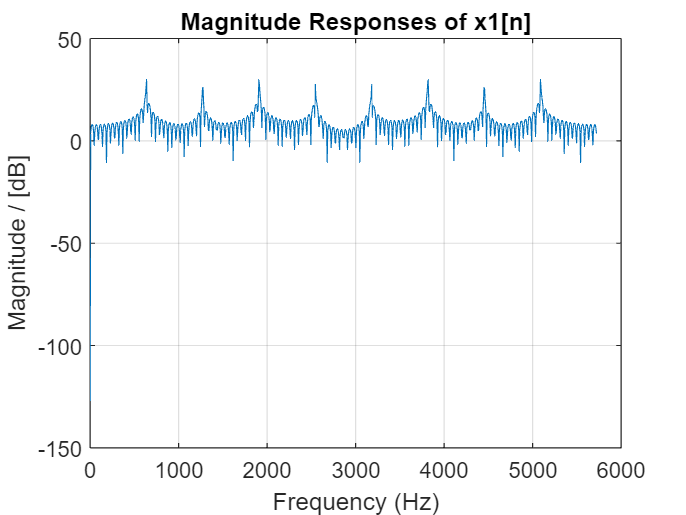


% Find magnitude reponse
N_FFT = 1024; % FFT size
X1 = fft(x1,N_FFT);
X2 = fft(x2,N_FFT);
f_axis = (0:N_FFT-1)*fs/N_FFT; % Frequency axis

% Plot magnitude 
figure;
plot(f_axis,10*log10(abs(X1)));
title('Magnitude Responses of x1[n]');
xlabel('Frequency (Hz)');
ylabel('Magnitude / [dB]');
grid on;

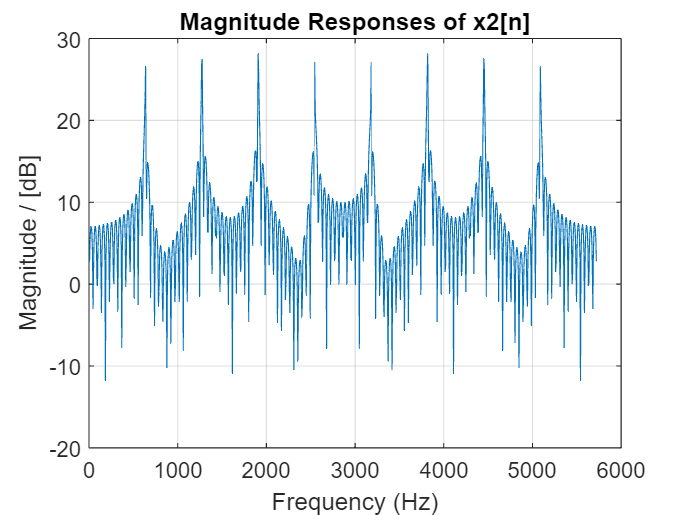

figure;
plot(f_axis,10*log10(abs(X2)));
title('Magnitude Responses of x2[n]');
xlabel('Frequency (Hz)');
ylabel('Magnitude / [dB]');
grid on;

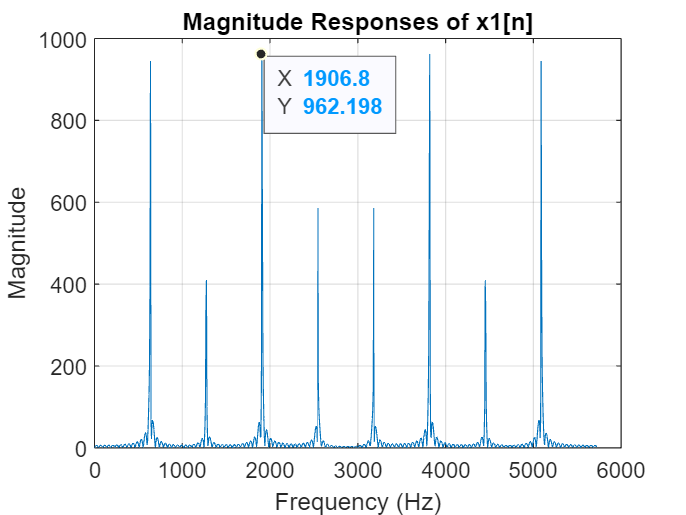

figure;
plot(f_axis,abs(X1));
title('Magnitude Responses of x1[n]');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

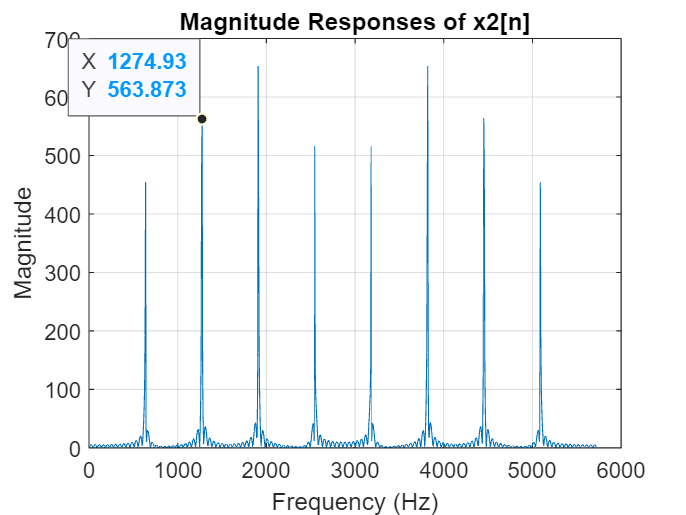

figure;
plot(f_axis,abs(X2));
title('Magnitude Responses of x2[n]');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

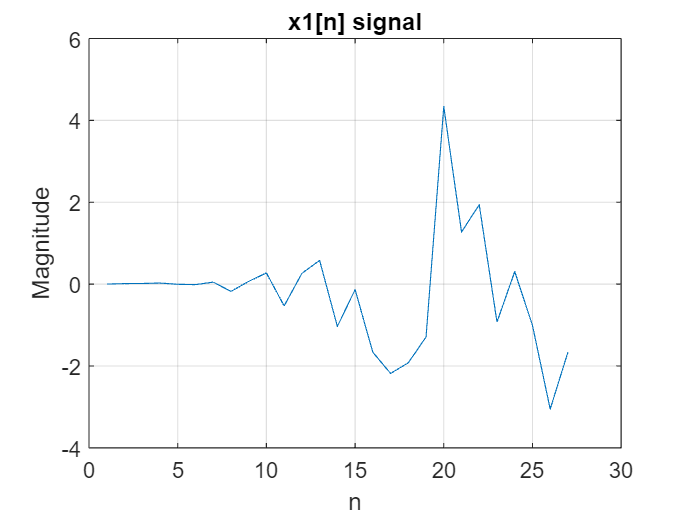

filt_x1 = filter(Num1, 1,x1);
filt_x2 = filter(Num2, 1,x2);

% Plot time signals
figure;
plot(1:27,filt_x1(1:27));
title('x1[n] signal')
xlabel('n');
ylabel('Magnitude');
grid on;

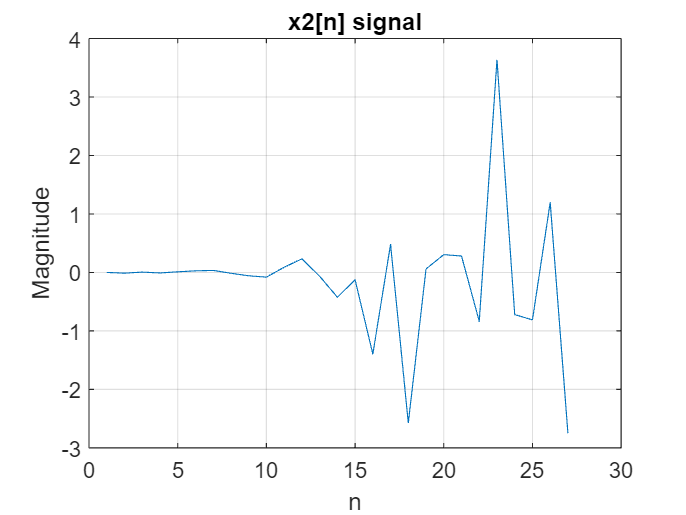

figure;
plot(1:27,filt_x2(1:27));
title('x2[n] signal')
xlabel('n');
ylabel('Magnitude');
grid on;

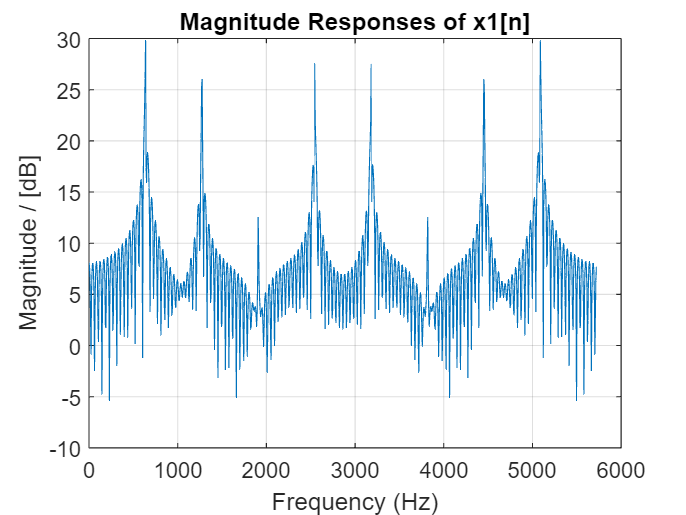


% Find magnitude reponse
N_FFT = 1024; % FFT size
X1 = fft(filt_x1,N_FFT);
X2 = fft(filt_x2,N_FFT);
f_axis = (0:N_FFT-1)*fs/N_FFT; % Frequency axis

% Plot magnitude 
figure;
plot(f_axis,10*log10(abs(X1)));
title('Magnitude Responses of x1[n]');
xlabel('Frequency (Hz)');
ylabel('Magnitude / [dB]');
grid on;

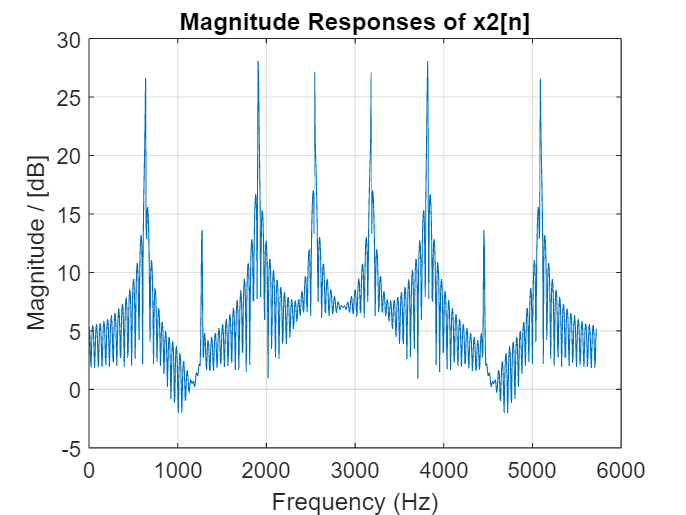

figure;
plot(f_axis,10*log10(abs(X2)));
title('Magnitude Responses of x2[n]');
xlabel('Frequency (Hz)');
ylabel('Magnitude / [dB]');
grid on;

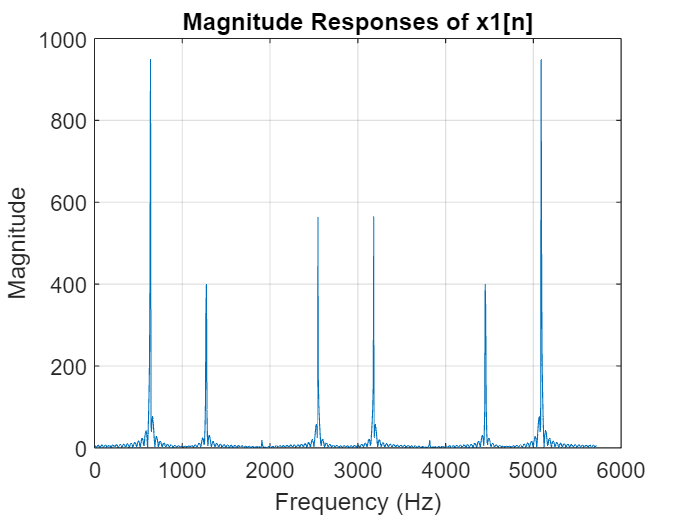

figure;
plot(f_axis,abs(X1));
title('Magnitude Responses of x1[n]');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

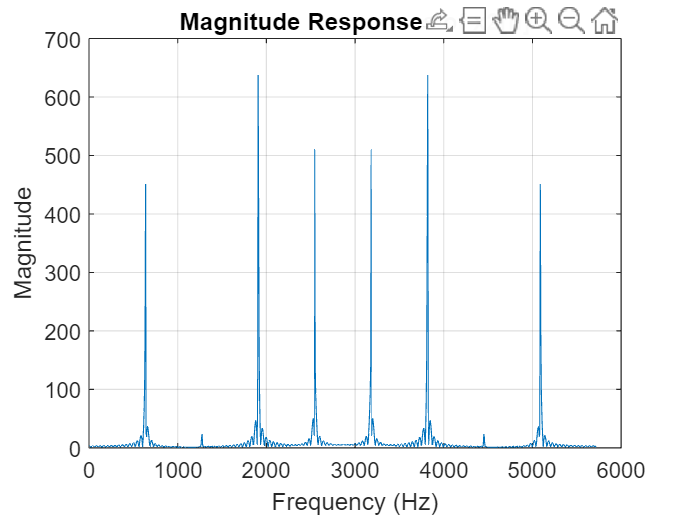

figure;
plot(f_axis,abs(X2));
title('Magnitude Responses of x2[n]');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

filter_a = single(Num1);
filter_b = single(Num2); 

save("AssData.mat")


FC_filtered = conv(filter_b,x2,"full")'

FC_filtered = 928×1 single column vector
         0
   -0.0123
    0.0057
   -0.0087
    0.0105
    0.0273
    0.0344
   -0.0138
   -0.0572
   -0.0806


AL_filtered = conv(filter_a,x1,"full")'

AL_filtered = 928×1 single column vector
    0.0023
    0.0126
    0.0160
    0.0265
   -0.0040
   -0.0125
    0.0496
   -0.1781
    0.0677
    0.2732


AL_ccs = readmatrix("Clion/cmake-build-debug/filter_AL.txt")

AL_ccs =     0.0023
    0.0126
    0.0160
    0.0265
   -0.0040
   -0.0125
    0.0496
   -0.1781
    0.0677
    0.2732


FC_ccs = readmatrix("Clion/cmake-build-debug/filter_FC.txt")

FC_ccs =          0
   -0.0123
    0.0057
   -0.0087
    0.0105
    0.0273
    0.0344
   -0.0138
   -0.0572
   -0.0806


diff_FC = 10*log10(sum((FC_ccs-FC_filtered).^2))

diff_FC = single
-98.7311

diff_AL = 10*log10(sum((AL_ccs-AL_filtered).^2))

diff_AL = single
-94.7042